# GIVEN A SINGLE OVERLOAD LOAD-TIME HISTORY

% Define min-max stress
s_min = [0 0 0 0 0]';
s_max = [1 1 2 1 1]'+0.000*randn(size(s_min));
% Define reversal based on the min-max stress vectors
revs = pv2revs(s_max, s_min);

% Apply rainflow counting algorithm
Rf = rainflow(revs(:,2));

% Apply the overload identifier
[~,Rfol] = rainflowol4(revs(:,2));


% Define min-max stress
s_min = [-2 -3 -1 -5 -3 -2 2]';
s_max = [1 5 3 4 1 3 6]'+0.000*randn(size(s_min));
% Define reversal based on the min-max stress vectors
revs = pv2revs(s_max, s_min);

% Apply rainflow counting algorithm
Rf = rainflow(revs(:,2));

% Apply the overload identifier
[~,Rfol] = rainflowol4(revs(:,2));

% Define a periodic overload with 2 overloads
s_min = [0 0 0 0 0 0 0]';
s_max = [1 3 1 1 2 1 1]';

% Define reversal based on the min-max stress vectors
revs = pv2revs(s_max, s_min);

% Apply rainflow counting algorithm
Rf1 = rainflow(revs(:,2));

% Define a periodic overload with 2 overloads
s_min = [0 0 0 0 0 0 0]';
s_max = [1 0 1 1 2 1 1]';

% Define reversal based on the min-max stress vectors
revs = pv2revs(s_max, s_min);

% Apply rainflow counting algorithm
Rf2 = rainflow(revs(:,2));

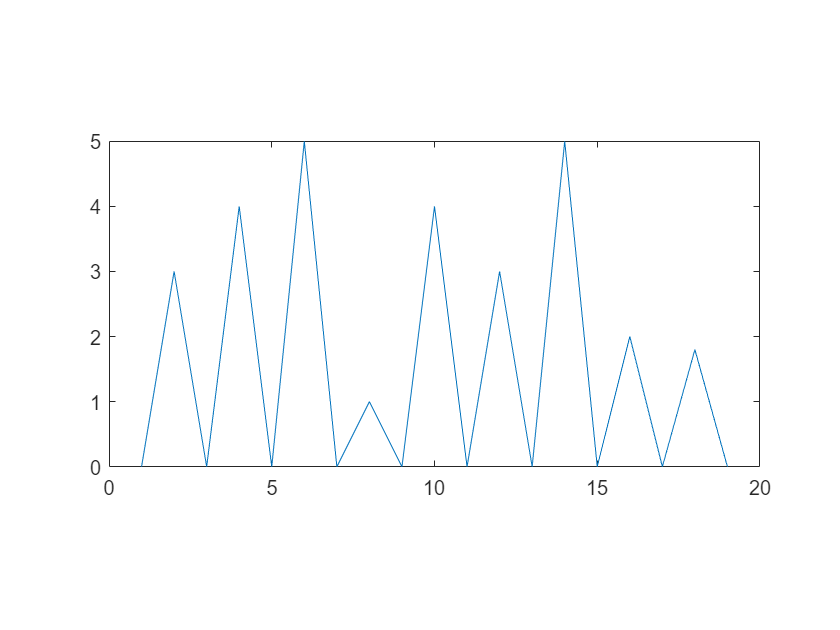

% -------------------- Test reversal history ----------------------------
close all
smin = [0 0 0 0 0 0 0 0 0]';
smax = [3 4 5 1 4 3 5 2 1.8]';
x = pv2revs(smax, smin);
x = [x(:,2); 0];
plot(x)
pbaspect([2 1 1])

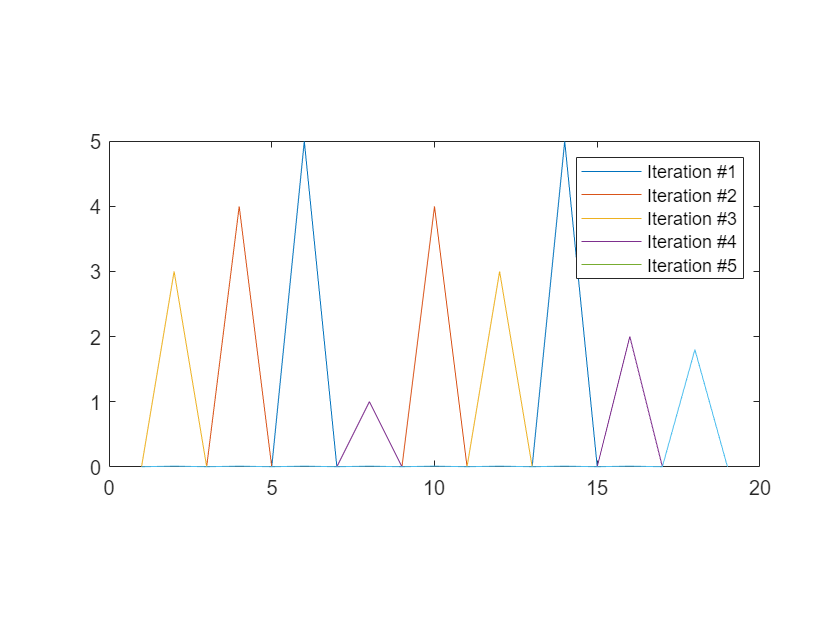

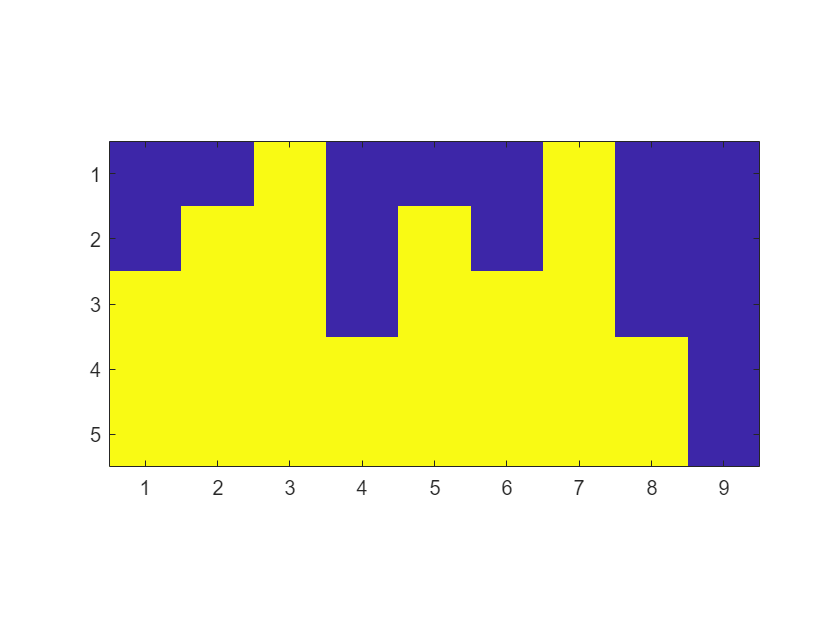

[sigmamax, ~, ~, ~, ~, ~, ~, ~] = drivefactor(x, 'true'); 
% -----------------------------------------------------------------------
tic
% -------------------- Run OL identifier --------------------------------
Omega = OLSpectrum(x, 'True');

% -----------------------------------------------------------------------

% -------------------- Run OL sifter ------------------------------------
OLI = OLIndex(Omega, 1);
toc

Elapsed time is 1.779887 seconds.


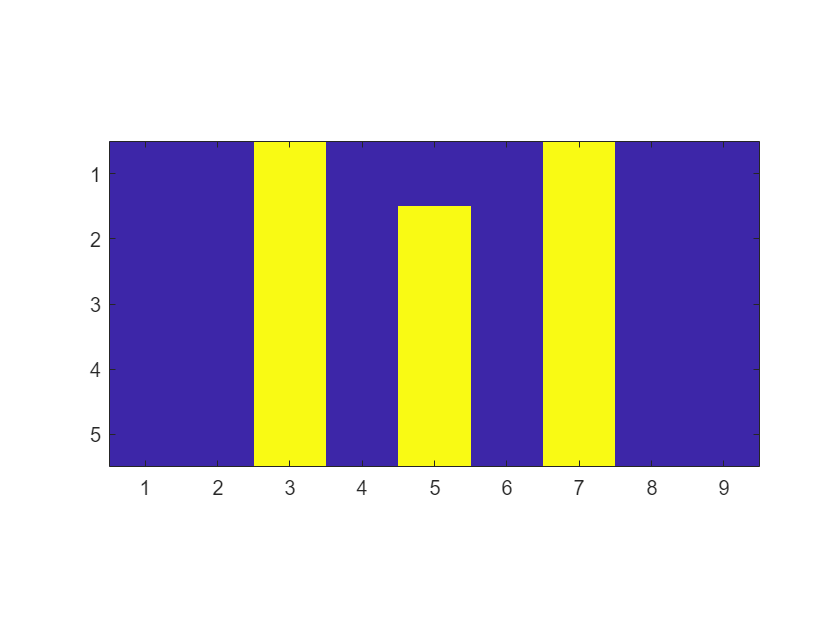

imagesc(OLI)
pbaspect([2 1 1])

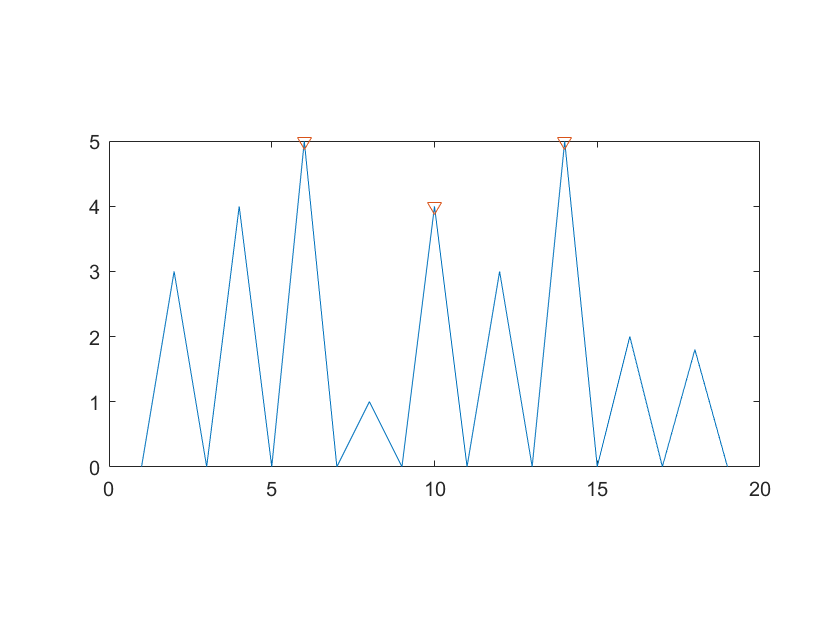

oli = [1:size(OLI,2); OLI(size(OLI,1),:)];
olindx = oli(1,oli(2,:)~=0);

plot(x)
hold on
plot(sigmamax(olindx,1),sigmamax(olindx,2),'v')
pbaspect([2 1 1])

% -------------------- Test reversal history ----------------------------
rng(1);
smin = [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0]';
smax = randi(10,1,length(smin))';
x = pv2revs(smax, smin);
x = [x(:,2); 0];
plot(x)

[sigmamax, sigmamin, lcr, ~, ~, ~, ~, ~] = drivefactor(x, 'true'); % call drivefactor for Smax, Smin, and \Delta S
% sigmamax(:,1) = 2:2:length(sigmamax(:,1))*2; % Assign indeces correspond to the maximum stress (even indeces)
sigmamax(sigmamax(:,2) < 0 ,2) = 0;
% -----------------------------------------------------------------------

% -------------------- Run OL identifier --------------------------------
Omega = OLSpectrum(x, 'True');
% -----------------------------------------------------------------------

% -------------------- Run OL sifter ------------------------------------
OLI = OLIndex(Omega, 1);
OLI = OLIndex(OLI, 1);
imagesc(OLI)

oli = [1:size(OLI,2); OLI(size(OLI,1),:)];
olindx = oli(1,oli(2,:)~=0);

plot(x)
hold on
plot(sigmamax(olindx,1),sigmamax(olindx,2),'v')